# Parameters

This file list the parameters used to evaluate the performance of the SIM. The parameters follows those listed in [1, Sec. VI]

## Simulation parameters

total_iteration=10^3;%referred to the number of transmitted packets, see [1, Sec. VI.D]


## Scenario parameters

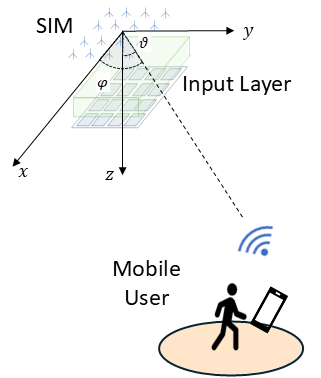

Fig. 1: Scenario

x_max=5;%maximum mobility area in the ground plane
y_max=5;%maximum mobility area in the ground plane
z_max=2.5;%height of the room
pos_SIM = [x_max/2 y_max/2 2.5]; % SIM position in meters
pos_MU = [2 4 1.5]; % MU position in meters
pos_MU_max=[x_max y_max 0];%max position of the MU in the positive ground plane
d_MU_SIM_max=norm(pos_SIM-pos_MU);%maximum distance from the MU to the SIM
theta_max=atan2(norm(pos_MU_max),d_MU_SIM_max)+pi;%maximum angle between the MU and SIM
theta_min=atan2(-norm(pos_MU_max),d_MU_SIM_max)+pi;%maximum angle between the MU and SIM

## **802.11ad parameters**

### **Transmitter Access Point (AP)**

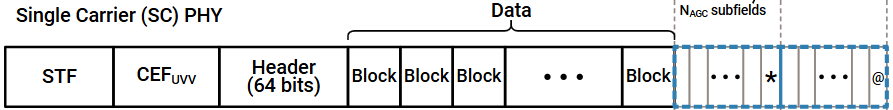

Fig 1: DMG Format PPDU for a single carrrier [2].

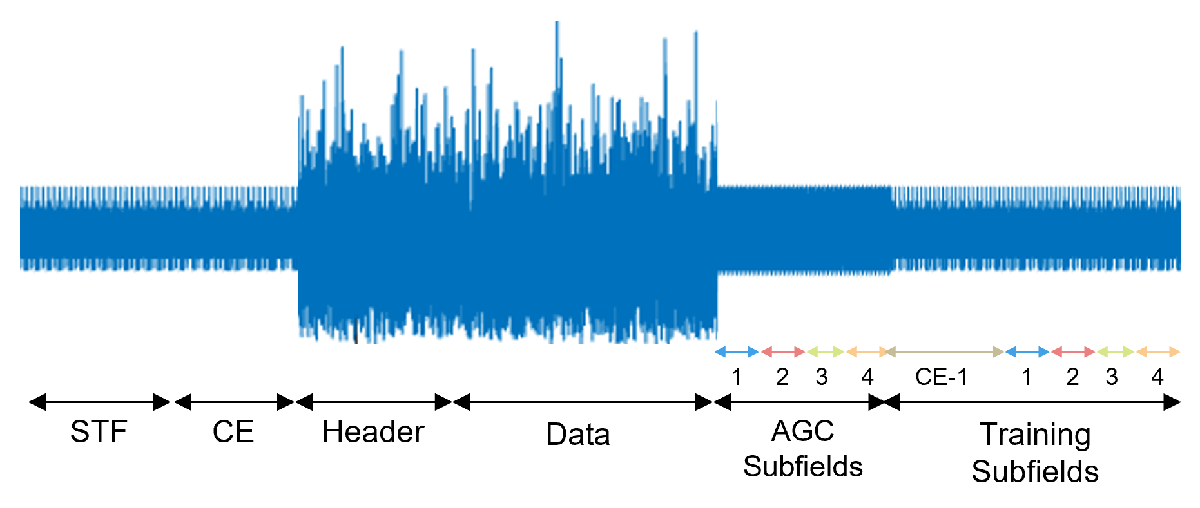

Fig 2: Time-domain DMG Format PPDU for a single carrrier [4].

Ptx_dBm = 20; % transmit power in dBm
Ptx = db2pow(Ptx_dBm-30);
% Create a configuration object for 802.11
cfgDMG_loc = wlanDMGConfig;
fc=60*10^9;%transmission frequency
lambda=physconst('LightSpeed')/fc;
% SNR_dB=[2 4 6 8 10];
idleTime=20e-6;% Idle time between packets [6]

fs = wlanSampleRate(cfgDMG_loc);%sampling time of the receiver node [6]
BW = 2640*10^6;%bandwidth, see [6]
%modulation format [3]
cfgDMG_loc.MCS="1"; % Single-carrier modulation
%packet format
%cfgDMG_loc.TrainingLength = 4;   % Use 4 training subfields (TRN) [3]
%cfgDMG_loc.PacketType = 'TRN-T'; % Transmitter training
cfgDMG_loc.PSDULength = 1; % PSDULength in bytes
ind_loc=wlanFieldIndices(cfgDMG_loc);
T_PPDU_loc=(double(ind_loc.DMGData(2))/fs)+idleTime;

## SIM paramaters

%N=16; %see [1, Sec. VI.C.]
N_x=[2 3 4 5 6 7 8 9 10 11 12 13 14 15];%[4 5 6 7 8 9];%SIM dimension of the zero Layer
N_x=4;
N_y=N_x; %to account for a balanced error in the x an y axes
N=N_x.*N_y;
d_x=lambda/2;

### Steering vector parameters

% k_x=3.3;%angle bin in the x dimension
% k_y=3.3;%angle bin in the y dimension
% psi_x=2*pi*(k_x)./max(N_x);%x-component of the electric angle; see caption in [1, Fig. 8]
% psi_y=2*pi*(k_y)./max(N_y);%y-component of the electric angle; see caption in [1, Fig. 8]
% psi_x=2*pi*rand();
% psi_y=2*pi*rand();

## Mobile User parameters

MU_speed=1;%meter per second

## Localization protocol parameters

T_coh=sqrt(9/16*pi)*physconst('LightSpeed')*MU_speed/fc

T_coh = 0.0066

%T=1024;%see [1, Sec. VI.C.]
%T_x=ceil(sqrt(T_coh/T_loc))
T_x=1:ceil(sqrt(T_coh/T_PPDU_loc));
T_y=T_x; %accounting for a balanced error in the x an y axes of the Fourier transform
T=T_x.*T_y

T =      1     4     9    16    25    36    49    64    81   100   121   144   169   196   225   256   289


## Noise parameters; see [3]

% Noise and interference parameters
noiseFigure = 7;                             % dB
thermalNoiseDensity = -174;                  % dBm/Hz
rxInterfDensity = -165.7;                    % dBm/Hz

% Calculate the corresponding noise power
totalNoiseDensity = 10*log10(10^((noiseFigure+thermalNoiseDensity)/10)+10^(rxInterfDensity/10));
var_noise_dB = totalNoiseDensity-30+10*log10(BW); % dB
var_noise=db2pow(var_noise_dB);


## SNR evaluation

%Free path loss in the direct link IRS-MU
Lr = (lambda/(2*pi*norm(d_MU_SIM_max)))^2;
SNR_dB=Ptx_dBm-30+pow2db(Lr)-var_noise_dB

SNR_dB = 21.6443

## Plotting parameters

font=15;

## References

[1] J. An et al., "Two-Dimensional Direction-of-Arrival Estimation Using Stacked Intelligent Metasurfaces," in IEEE Journal on Selected Areas in Communications, vol. 42, no. 10, pp. 2786-2802, Oct. 2024. DOI [10.1109/JSAC.2024.3414613](https://doi.org/10.1109/JSAC.2024.3414613)

[2] WLAN PPDU Structure, [https://de.mathworks.com/help/wlan/gs/dmg-ppdu-structure.html](https://de.mathworks.com/help/wlan/gs/dmg-ppdu-structure.html)

[3] Model Reconfigurable Intelligent Surfaces with CDL Channels [https://ch.mathworks.com/help/5g/ug/model-reconfigurable-intelligent-surfaces-with-cdl-channels.html](https://ch.mathworks.com/help/5g/ug/model-reconfigurable-intelligent-surfaces-with-cdl-channels.html)

[4] [https://ch.mathworks.com/help/wlan/ug/802-11ad-waveform-generation-with-beamforming.html](https://ch.mathworks.com/help/wlan/ug/802-11ad-waveform-generation-with-beamforming.html)

[5] [https://ch.mathworks.com/help/phased/ug/signal-collection.html](https://ch.mathworks.com/help/phased/ug/signal-collection.html)

[6] [https://ch.mathworks.com/help/wlan/ref/wlanwaveformgenerator.html#bvdi39e-4](https://ch.mathworks.com/help/wlan/ref/wlanwaveformgenerator.html#bvdi39e-4)